**Pseudo 4D Plot**

In this project, I explored the visualization of a 3D surface plot using MATLAB. A 3D surface plot is a powerful tool for representing relationships between three variables, where the z-axis provides depth to the visualization.

To begin, I defined the x and y values using MATLAB’s `meshgrid` function, creating a grid of points within the range −π-\pi−π to π\piπ. This grid served as the foundation for the surface. The z-values were then calculated using a mathematical expression that combined the x and y values with trigonometric functions, specifically z=x⋅y⋅sin (x)⋅cos (y)z = x \cdot y \cdot \sin(x) \cdot \cos(y)z=x⋅y⋅sin(x)⋅cos(y). This formula generated an intricate surface with peaks and valleys, reflecting the interplay between the variables.

I visualized the surface using the `surf` function, which rendered the grid as a smooth, colorful surface. To enhance clarity, I added labels to the x, y, and z axes, a title to describe the plot, and a grid for visual alignment. I used the 'jet' colormap to assign vibrant colors to different z-values, providing an intuitive representation of height variations. Adding a colorbar further improved the visualization by linking specific colors to corresponding z-values.

This project demonstrated how mathematical expressions can be brought to life through 3D plotting.

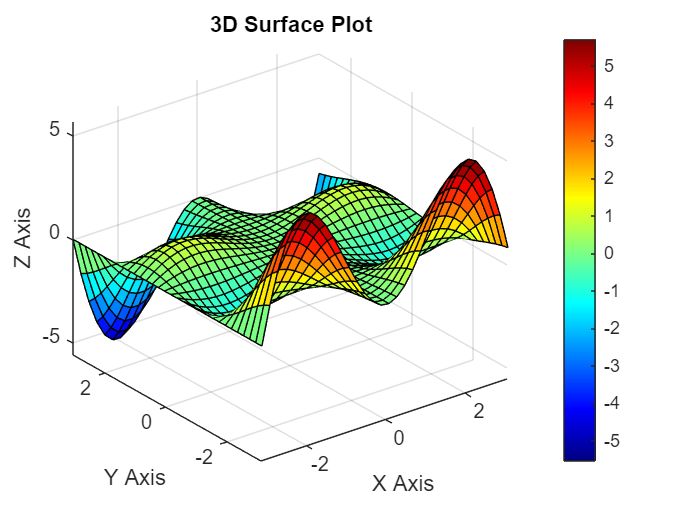

% Creating a 3D Surface Plot
% I want to visualize a 3D surface defined by x, y, and z.

% Generate x and y values
[x, y] = meshgrid(-pi:0.2:pi, -pi:0.2:pi);

% Define the surface function
z = x .* y .* sin(x) .* cos(y);

% Plot the surface
figure;
surf(x, y, z);
xlabel('X Axis');
ylabel('Y Axis');
zlabel('Z Axis');
grid on;
colormap('jet');
colorbar;
title('3D Surface Plot');